# Weather-git-scraping

GitHub Actions used to scrape the weather️ 

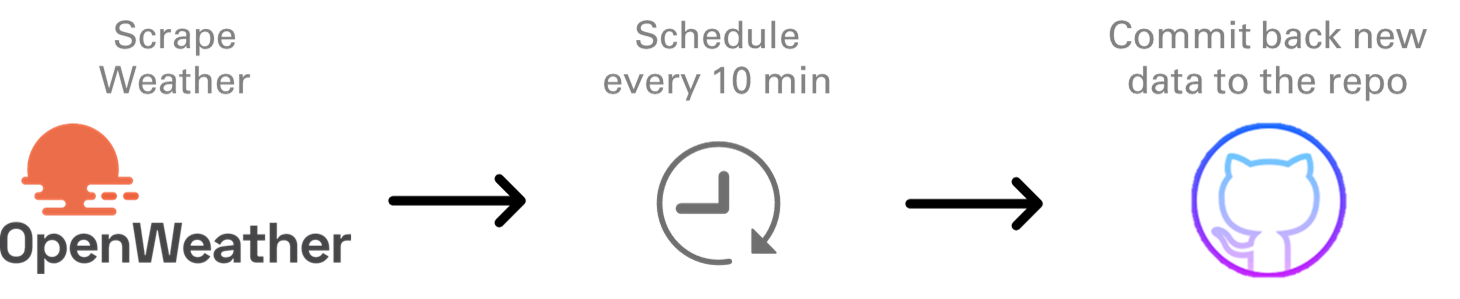

### Initialize

apikey = getenv("OWM_KEY");
% T = getWeather(apikey);
% writetable(T,"weather_boston.csv")

### Iterate

T = readtable("weather_boston.csv");
T2 = getWeather(apikey);
T = [T;T2]

T = 2x9 table
    temp     feels_like    temp_min    temp_max    pressure    humidity    sea_level    grnd_level            time        
    _____    __________    ________    ________    ________    ________    _________    __________    ____________________

    76.95      76.84        74.25        79.5        1011         53         1011          1007       21-Jul-2025 16:17:22
    76.84      76.66        74.25       79.07        1011         52         1011          1007       21-Jul-2025 16:38:15


writetable(T,"weather_boston.csv")

### Automate

Create [.github/workflows/scraper.yml](matlab:open('.github/workflows/scraper.yml'))

### Settings

Make sure to grant read AND write workflow permissions to the Actions in the repo settings:

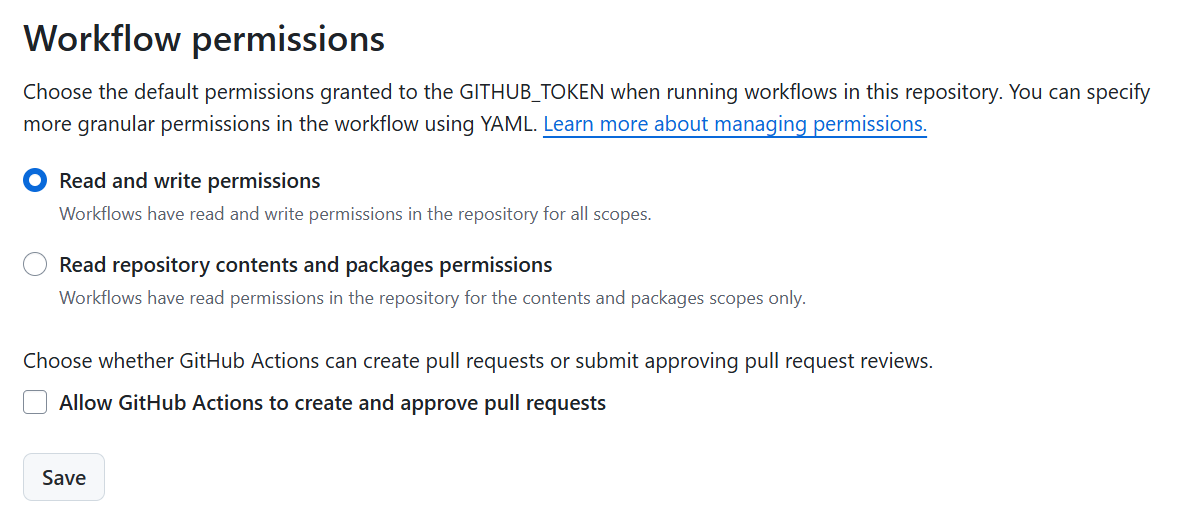

### Utils

function T = getWeather(apikey)
url = "https://api.openweathermap.org/data/2.5/weather?q=Boston&units=imperial&appid="+apikey;
data = webread(url,weboptions(Timeout=10));
weather = data.main;
weather.time = datetime(data.dt,"ConvertFrom","posixtime");
T = struct2table(weather);
end

Don't forget to [add badge to Open in MATLAB Online](https://www.mathworks.com/products/matlab-online/git.html)

`[![Open in MATLAB Online](https://www.mathworks.com/images/responsive/global/open-in-matlab-online.svg)](https://matlab.mathworks.com/open/github/v1?repo=yanndebray/git-scraping101&file=weatherscraper.mlx)`

export weatherscraper.mlx README.md;